# rHW 4 Part I:  Prosthesis Mid-level Control.

## 1.a. Load the data

In this homework, we will simulate an impedance-based finite state machine controller for a knee and ankle prosthesis.  We will largely follow the "Design and Control of a Powered Transfemoral Prosthesis" by Sup et al, 2008.  

The data this time includes Ankle and Knee moments (torques) calculated using specialized software.  Positive moments and velocites at the ankle are in dorsiflexion (same as last HW), and at the knee are in extension.  I have also removed the markers, which we will not need.   

*Note*: This homework will create a bit more problem-solving than last homework.

clear; close all; clc
addpath('HW4_data\', 'HW4_functions\')
file2load  = "0deg_1.2ms_HW4.mat"; % Load the intermediate walking speed trial
load(file2load);
head(D) % Show the top 8 rows of the data table (D)

ans = 8×21 table
       Time            R_COP               L_COP                       R_F                             L_F                            R_Accel                            R_Gyro                            L_Accel                          L_Gyro                R_Ankle_Angle    L_Ankle_Angle    R_Ankle_Velocity    L_Ankle_Velocity    R_Ankle_Moment    L_Ankle_Moment    R_Knee_Angle    L_Knee_Angle    R_Knee_Velocity    L_Knee_Velocity    R_Knee_Moment    L_Knee_Moment
    __________    ________________    ________________    _____________________________  

## 1.b Create a finite state machine

**Modify** "GetGaitState" so that it takes in **D**, the data table, and returns the gait state for the right leg only; then, run this cell to produce a plot of gait state vs time.  We will describe gait state as an integer 1-4, according to the following: 1: Early Stance ("Stance Flexion"), 2: Late Stance ("Pre-swing"), 3: Early Swing (Swing flexion), 4: Late Stance (Swing Extension).  You will need to use a for-loop to iterate through D.  The state machine is defined as follows:

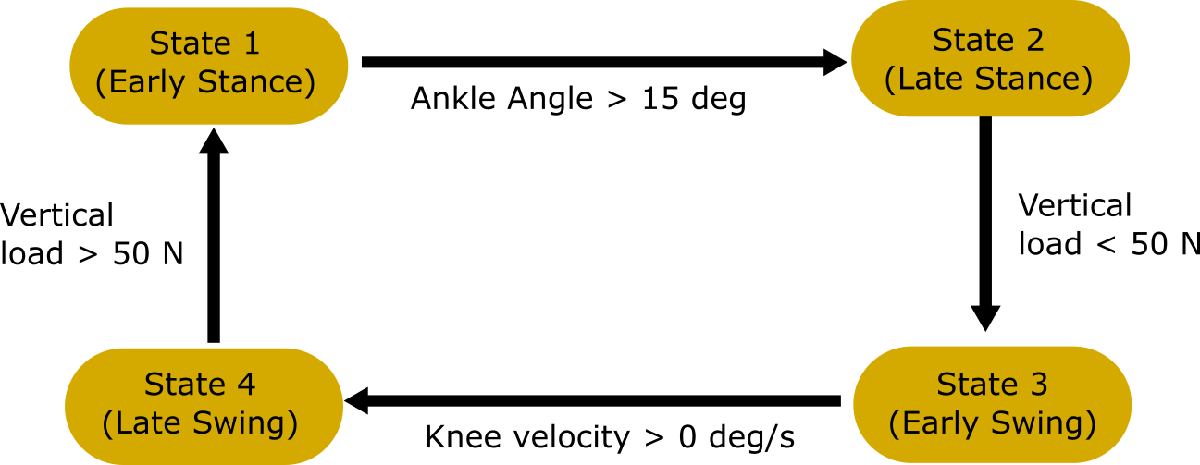

Assume our "prosthesis" has encoders on the ankle and knee (thus angles and velocities can be measured), it can accurately produce the torque that we command, and that it can sense force with a load cell in the shank--we will use our force plate to emulate this load cell (e.g., use *D.R_F(:,3)*).  [20]

***Hint***: Your function should keep track of the current_state, and your if/else conditions should check for both the current state and the heuristic you are checking.

***Hint***: This is what your generated plot should look like:

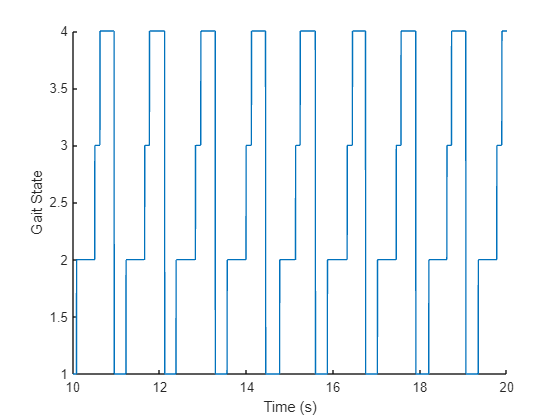

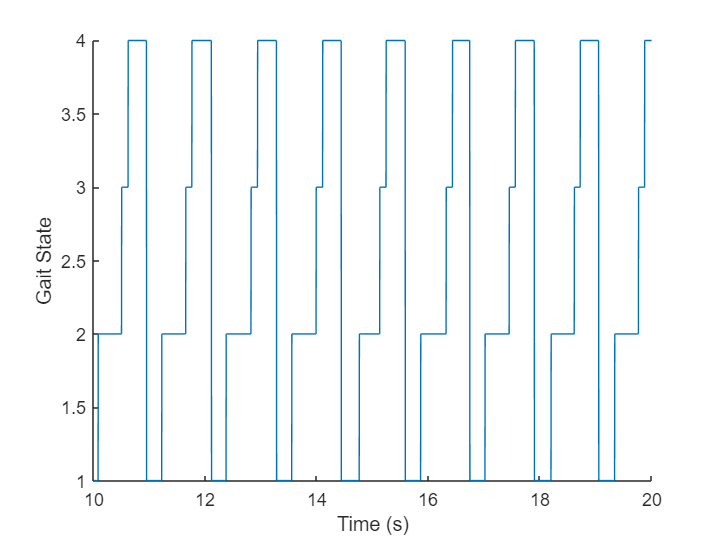

% Do not modify this code.  Only modify 'GetGaitState.m'
D.R_GaitState = GetGaitState(D);
figure; hold on
plot(D.Time, D.R_GaitState)
xlabel('Time (s)')
ylabel('Gait State')
xlim([10,20]) % to relicate above figure

## 1.c Identify transition criteria from plots

Use subplots to plot gait_state, ankle angle, knee angle, and vertical force for approximately ONE STRIDE.  Copy this plot, and mark it up using whatever tool you would like (powerpoint, google slides, etc).  Point out the transition criteria for each change in state in the appropriate subplot. [10]

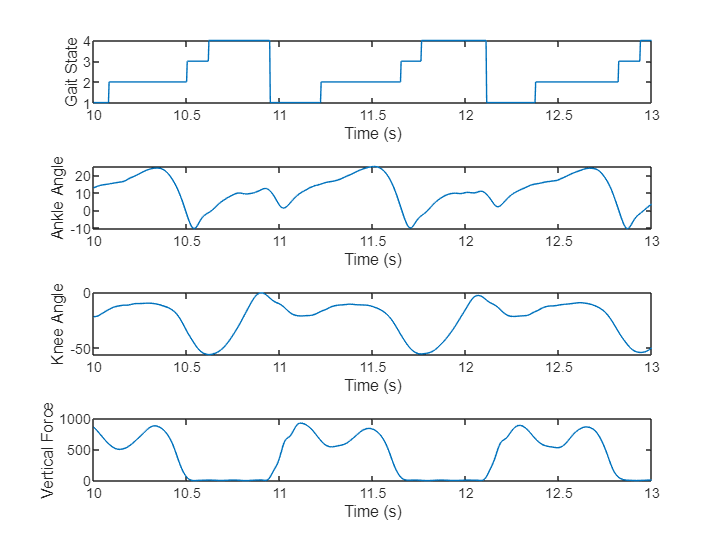

% your code here
figure; hold on
tiledlayout(4,1)
nexttile
plot(D.Time, D.R_GaitState)
xlabel('Time (s)')
ylabel('Gait State')
xlim([10, 13])

nexttile
plot(D.Time, D.R_Ankle_Angle)
xlabel('Time (s)')
ylabel('Ankle Angle')
xlim([10, 13])

nexttile
plot(D.Time, D.R_Knee_Angle)
xlabel('Time (s)')
ylabel('Knee Angle')
xlim([10, 13])

nexttile
plot(D.Time, D.R_F(:, 3))
xlim([10, 13])
xlabel('Time (s)')
ylabel('Vertical Force')
xlim([10, 13])
hold off

<paste your image here>

    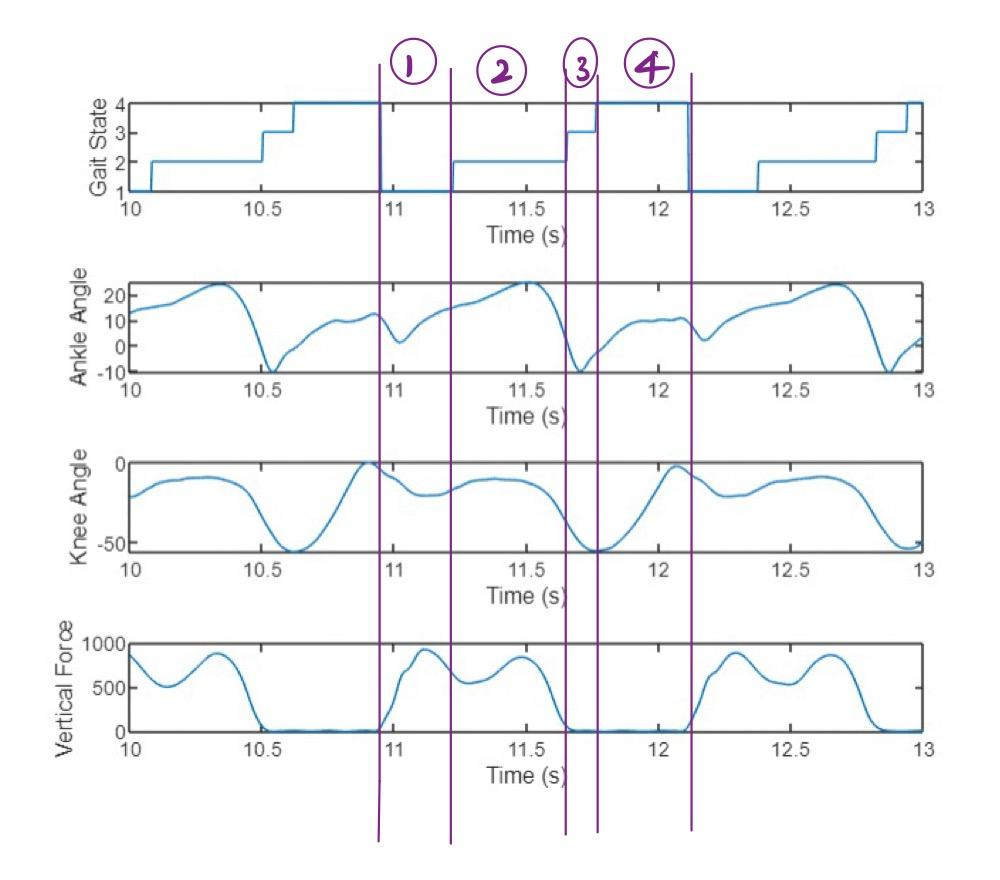

## 2.a: Develop Ankle Impedance Controller

Now that we have a working state machine, we can see how well spring-dampers can emulate the biological ankle torque for our participant.  The impedance parameters we will use are from Table 4 in the reading, which were fit to "Prototypical Gait."

**Modify** "ImpedanceController.m" to take in controller_params, gait state, angle, and velocity, and return a vector for the actuator torque.  Use a for loop to iterate through the data, and use an if/else statement to get the correct stiffness, damping, and setpoint for the current state. [20]

*Note: *Sign convention is important again.  Let's keep our dorsiflexion moment and angle positive, and let's keep our stiffness and damping parameters positive, so you will need to multiply your actuator torque by -1 **inside** the ImpedanceController function to match our convention (it will be obvious if you've forgotten, as the plotted actuator torques will look opposite to the biological ankle moments).

*Note*: Your plot should look like the following:

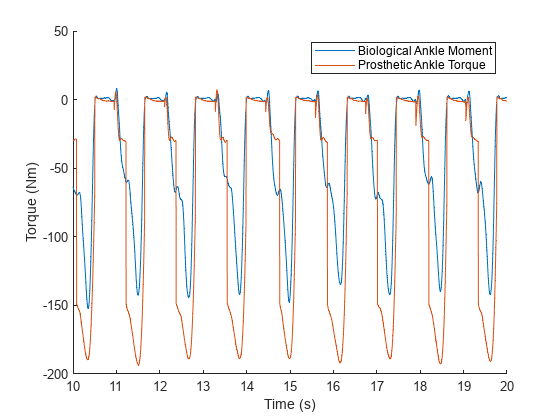

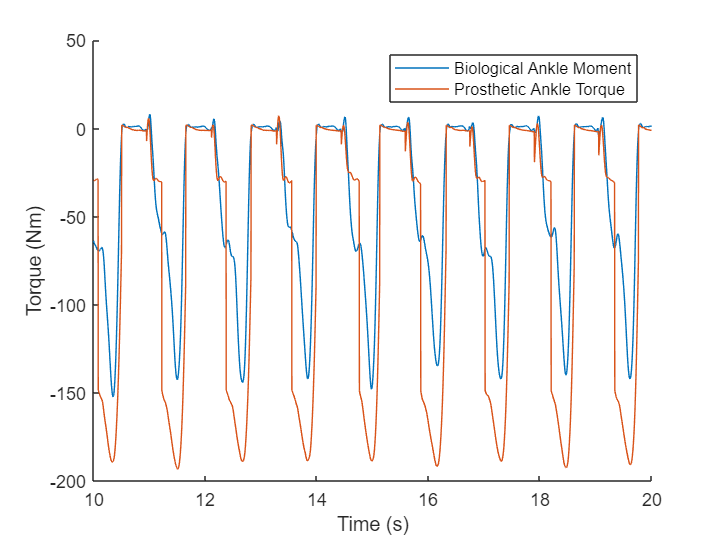

% Do not modify this code; only modify "ImpedanceController.m"
ankle_controller_params = ...
    [1.35, 4.50, 0.04, 0.134,...
    0.118, 5e-3, 3e-3, 2e-3,...
    -5, -18, 23, 2]; % These values taken from the paper

ankle_actuator_torque = ImpedanceController(ankle_controller_params, D.R_GaitState, D.R_Ankle_Angle, D.R_Ankle_Velocity);
figure; hold on
plot(D.Time, D.R_Ankle_Moment)
plot(D.Time, ankle_actuator_torque)
legend(["Biological Ankle Moment","Prosthetic Ankle Torque"])
xlabel('Time (s)')
ylabel('Torque (Nm)')
xlim([10,20])
hold off;

## 2.b: Assess fit.

How well did our impedance controller do at mimicking biological ankle moments?  There are two common ways to describe the goodness of fit:  R-squared, and RMSE.  Calculate both results for our impedance controller relative to the Biological Ankle Moment.  To calculate R-squared, you can either square the correlation coefficient (Matlab's "corrcoef" function), or fit a linear model ("fitlm"). [5]  **Answer the questions below.**

% Your code here
%compare bio & pros ankle movement
bio = D.R_Ankle_Moment';
pros = ankle_actuator_torque;

%R-squared
R_corr = corrcoef(bio, pros);
R_sq = R_corr(1,2)^2;
disp(R_sq)

    0.8070




%RMSE
error_ank_new = bio - pros;
RMSE_kne_new = sqrt(mean(error_ank_new.^2));
disp(RMSE_kne_new)

   47.3647



***Questions******:***

*What is the RMSE? (Don't forget units!) [2]*

<your answer here> 47.3647 Nm

*What is the R-squared? [2]*

<your answer here> 80.7%

*Look at Figure 10 in the reading.  The impedance parameters seem to do a much better job for them--why is that?  Hint: where did they get this target data? [5]*

<your answer here>

1) The graph in the reading is obtained by testing and validating on the same data of a 75kg subject from Winter (1991)

2) Gait trials were on a treadmill which provided a constant walking speed

3) The gait data of Fig 10 and Table 4 is obtained by observation and is not theoretical

## 2.c: Knee impedance controller

**Perform the same analysis for the knee.**  Use Table 4 from the reading to get the impedance parameters (ignore the k2 column).  Plot the biological knee moment and prosthetic knee torque (similar to above), from time T = 10s to 20s. Calculate RMSE and R-squared for the knee. [10]

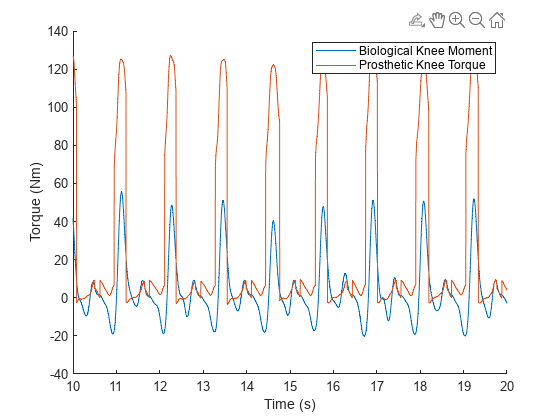

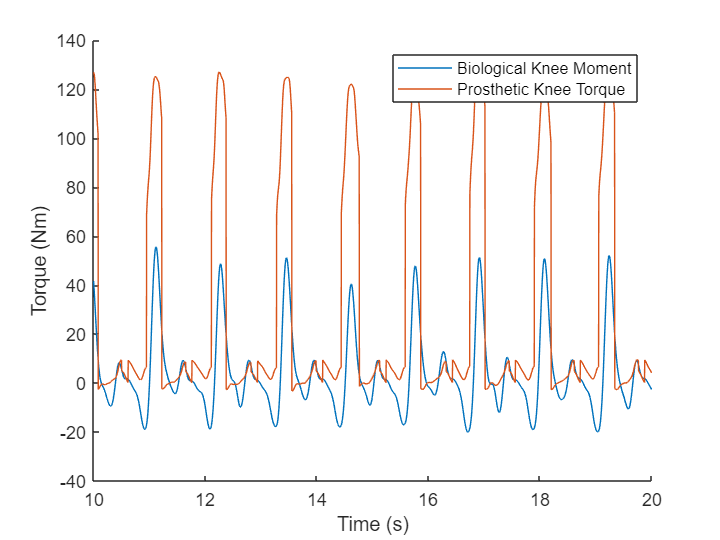

% Your Code Here
%Using the parameters from Table 4
knee_controller_params = ...
    [3.78, 0, 0, 0.093,...
    25e-3, 30e-3, 16e-3, 13e-3,...
    12, 37, 52, 44];

knee_actuator_torque = ImpedanceController(knee_controller_params, D.R_GaitState, D.R_Knee_Angle, D.R_Knee_Velocity);
figure; hold on
plot(D.Time, D.R_Knee_Moment)
plot(D.Time, knee_actuator_torque)
legend(["Biological Knee Moment","Prosthetic Knee Torque"])
xlabel('Time (s)')
ylabel('Torque (Nm)')
xlim([10,20])
hold off;

%from 2b:
bio = D.R_Knee_Moment';
pros = knee_actuator_torque;

%R-squared
R_corr = corrcoef(bio, pros);
R_sq = R_corr(1,2)^2;
disp(R_sq)

    0.5432




%RMSE
error_ank_new = bio - pros;
RMSE_kne_new = sqrt(mean(error_ank_new.^2));
disp(RMSE_kne_new)

   45.2840



***Questions******:***

*What is the RMSE? (Don't forget units!) [2]*

<your answer here> 45.2840 Nm

*What is the R-squared? [2]*

<your answer here> 54.32%

## 3.a: Optimize Impedance Parameters

In this section, we will use optimization to determine the best impedance parameters for our subject.  The goal is to find the impedance parameters that minimize error between the actuator torque and the biological moment. I have largely written this code for you--including the bounds and initial point.  

**Modify** "ImpedanceControlCostFunction.m", which is our custom cost function used by the optimization. This cost function takes in a set of impedance parameters provided by the optimization ("impedance_params_to_evaluate") as well as gait state, joint angle, joint velocity, and joint biological torque, which are needed to calculate actuator torque. Your goal within this cost function is to 1) calculate actuator torque based on the passed impedance parameters (luckily, you already wrote the function ImpedanceController.m to do this easily!), and 2) calculate the RMSE ("error") between actuator torque and biological moment to pass back to the optimization algorithm and drive the gradient descent. 

When run, the optimization algorithm iteratively passes your specificed cost function a new batch of parameters to try. In the *fmincon* code below, the variable we are optimizing over is represented by "x". In the cost function, you will see this variable is specified as "impedance_params_to_evaluate" variable. You do not need to modify any of the code below, only the cost function. If you want to understand the optimization more deeply, see Matlab's help page for *fmincon.*

**Run this cell** to generate the optimal impedance parameters ('opt_impedance_params_joint'), simulate the prosthetic joint torque, and plot your results compared to biological joint torques. Your output should look similar to the plots generated in Parts 2a and 2c, but we would expect a better fit. [10]

%Do not modify this cell
lb = [0, 0, 0, 0, 0, 0, 0, 0, -100, -100, -100, -100]; % lower bounds for the 12 parameters
ub = [100, 100, 100, 100, 100, 100, 100,100, 100, 100, 100,100]; % upper bounds for the 12 parameters

opt_impedance_params_ankle = fmincon(@(x)ImpedanceControlCostFunction(x, ...
    D.R_GaitState, D.R_Ankle_Angle, D.R_Ankle_Velocity, D.R_Ankle_Moment), ...
    ankle_controller_params,[],[],[],[], lb, ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


opt_impedance_params_knee = fmincon(@(x)ImpedanceControlCostFunction(x, ...
    D.R_GaitState, D.R_Knee_Angle, D.R_Ankle_Velocity, D.R_Knee_Moment), ...
    knee_controller_params,[],[],[],[], lb, ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


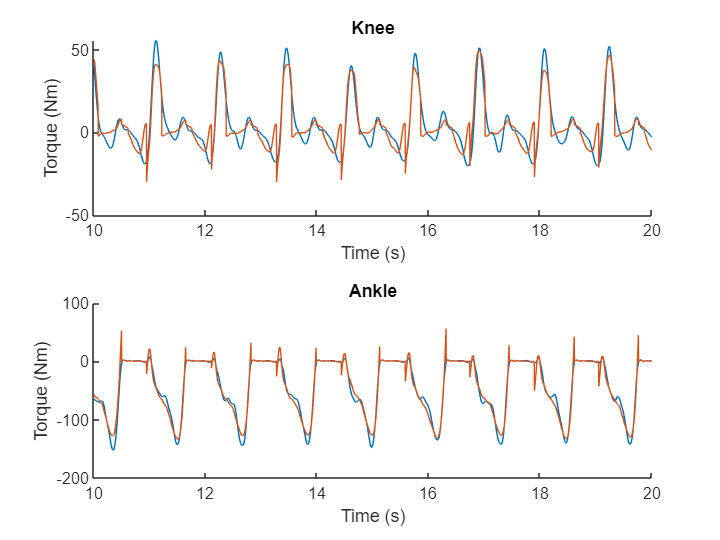

ankle_actuator_torque = ImpedanceController(opt_impedance_params_ankle, D.R_GaitState, D.R_Ankle_Angle, D.R_Ankle_Velocity);
knee_actuator_torque = ImpedanceController(opt_impedance_params_knee, D.R_GaitState, D.R_Knee_Angle, D.R_Knee_Velocity);

tiledlayout(2,1)
ax1 = nexttile; 
hold on
plot(D.Time, D.R_Knee_Moment)
plot(D.Time, knee_actuator_torque)
xlabel('Time (s)')
ylabel('Torque (Nm)')
title('Knee')
xlim([10,20])

ax2 = nexttile; 
hold on
plot(D.Time, D.R_Ankle_Moment)
plot(D.Time, ankle_actuator_torque)
xlabel('Time (s)')
ylabel('Torque (Nm)')
title('Ankle')
xlim([10,20])

%from 2b:
%RMSE for ankle
error_ank_new = D.R_Ankle_Moment' - ankle_actuator_torque;
RMSE_ank_new = sqrt(mean(error_ank_new.^2));
disp(RMSE_ank_new)

    8.3291



%RMSE for knee
error_kne_new = D.R_Knee_Moment' - knee_actuator_torque;
RMSE_kne_new = sqrt(mean(error_kne_new.^2));
disp(RMSE_kne_new)

    7.5849



***Questions****:*

*What is the RMSE for the ankle? [2]*

<your answer here> 8.3291 Nm

*What is the RMSE for the knee? [2]*

<your answer here> 7.5849 Nm

## 3.b: Try LG-walking impedance parameters for ramp ascent

We just found the optimal impedance parameters that replicate biological torque for this subject, and for the task of level ground walking.  A big question is whether we need different impedance parameters for different tasks. In this block, I have written the code for you to load in a walking trial from the same participant walking uphill at a 6 degree incline. It has been added to your workspace as a new Table:** D_RA** (RA = ramp ascent). 

**Complete this code block to**: 

1) Apply your existing state machine to this new ramp ascent data set using your function GetGaitState(...).

2) Apply your existing impedance controller to this new ramp ascent data using your function ImpedanceController(...). Use the optimized knee and ankle impedance parameters that you calculated for level ground walking in Parts 2a and 2c. 

3) Plot the knee and ankle biological moments and prosthesis torques vs. time (you have code for this already in previous sections). 

4) Calculate the RMSE 

[15]

**When completed, answer the questions below**.

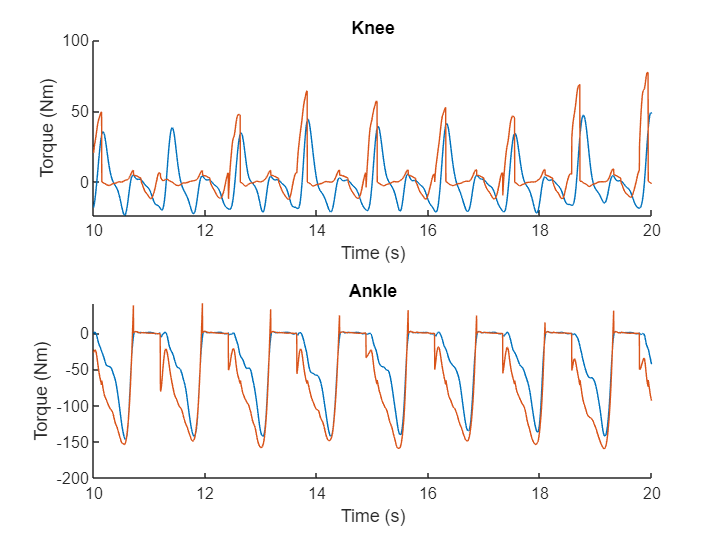

file2load  = "6deg_1.2ms_HW4.mat"; % Load the intermediate walking speed trial
D_tmp = load(file2load);
D_RA = D_tmp.D; 

% your code here
D_RA.R_GaitState = GetGaitState(D_RA);

ankle_actuator_torque_new = ImpedanceController(opt_impedance_params_ankle, D_RA.R_GaitState, D_RA.R_Ankle_Angle, D_RA.R_Ankle_Velocity);
knee_actuator_torque_new = ImpedanceController(opt_impedance_params_knee, D_RA.R_GaitState, D_RA.R_Knee_Angle, D_RA.R_Knee_Velocity);

tiledlayout(2,1)
nexttile; 
hold on
plot(D_RA.Time, D_RA.R_Knee_Moment)
plot(D_RA.Time, knee_actuator_torque_new)
xlabel('Time (s)')
ylabel('Torque (Nm)')
title('Knee')
xlim([10,20])

nexttile; 
hold on
plot(D_RA.Time, D_RA.R_Ankle_Moment)
plot(D_RA.Time, ankle_actuator_torque_new)
xlabel('Time (s)')
ylabel('Torque (Nm)')
title('Ankle')
xlim([10,20])
hold off


%RMSE for ankle
error_ank_new = D_RA.R_Ankle_Moment' - ankle_actuator_torque_new;
RMSE_ank_new = sqrt(mean(error_ank_new.^2));
disp(RMSE_ank_new)

   32.0005




%RMSE for knee
error_kne_new = D_RA.R_Knee_Moment' - knee_actuator_torque_new;
RMSE_kne_new = sqrt(mean(error_kne_new.^2));
disp(RMSE_kne_new)

   20.2619



***Questions:***

*What is the RMSE for the knee and ankle, and how does it compare to the task the parameters were optimized for? [2]*

<your answer here> 

RMSE_Ankle = 32.005Nm ; RMSE_Knee = 20.2619

The parameters were optimised for 3a, normal walking. As seen the RMSE values in 3a are much lower than the values obtained above.

Hence, the optimization was suceesful for the task 3a.

## 4) High-Level Mode Classification

### OVERVIEW: 

The purpose of this section is to build a high level classifier (using linear discriminant analysis, LDA) to identify if someone is about to take a step on level ground, or at an incline or decline. As you saw in Question 3b, the impedance parameters for a given gait mode don't translate well to other modes. So each gait mode (level walking, incline walking, decline walking) requires ts own state machine with its own unique transition criteria and impedance parameters. You can imagine a multi-mode state machine might look something like this (we saw other examples in class!): 

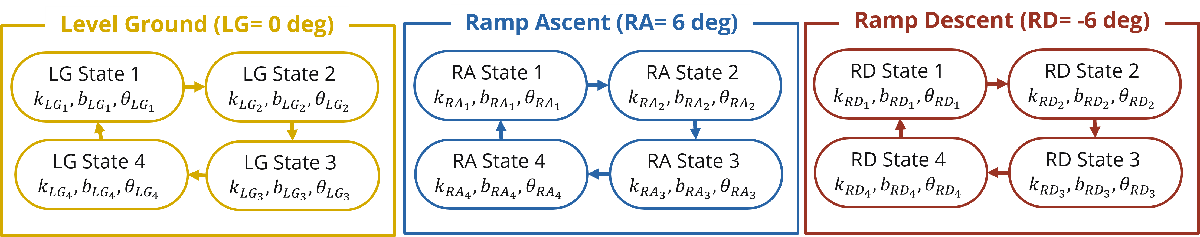

**The key takeaway here: it is really important that we know what ambulation mode (LG, RA, RD) the person is in so that we can appropriately control the prosthesis. It is also important that we know this information BEFORE they put their foot on the ground (heel strike). The prosthesis will need to behave differently beginning at heel strike, depending on the chosen ambulation mode. **

We will simulate this behavior by using the data collected in the lab. We have three files that are approximately 30 s each; one of someone walking at 0 deg, one at -6 deg (decline walking) and one at 6 deg (incline walking). 

### Load and arrange the new data 

**Run the following cell**  to organize this data into an easy-to-use matrix, **D_all **(you have nothing to add here!). Notice that the data from all three files have been concatentated one after another. A new variable, **D_all.RampAngle**, tells us which samples belong to which file.  Examine the output of the table to see this new column at the end. 

files2load  = ["neg6deg_1.2ms_HW4.mat", "0deg_1.2ms_HW4.mat", "6deg_1.2ms_HW4.mat"];
ramp_angles = [-6, 0, 6];
D_all = [];

for file_idx = 1:length(files2load)
    load(files2load(file_idx));
    D.RampAngle(:) = ramp_angles(file_idx); % Add a new column containing the ramp angle
    D_all = [D_all; D]; %Concatenate to make one long Data table with all three trials.
end
head(D_all)

ans = 8×22 table
       Time            R_COP               L_COP                     R_F                              L_F                              R_Accel                          R_Gyro                           L_Accel                           L_Gyro               R_Ankle_Angle    L_Ankle_Angle    R_Ankle_Velocity    L_Ankle_Velocity    R_Ankle_Moment    L_Ankle_Moment    R_Knee_Angle    L_Knee_Angle    R_Knee_Velocity    L_Knee_Velocity    R_Knee_Moment    L_Knee_Moment    RampAngle
    __________    ________________    ________________    ____________

## 4.a High Level Mode Classification

Once the foot is flat on the ground, IMUs are quite good at determing ground angle with simple analytical techniques, but we want to know the ground angle just before heel strike to change our early stance impedance parameters appropriately, before the foot has even touched the ground.  To do this, we will train a Linear Discriminant Analysis model. In our first attempt, we will train the LDA on instantaneous data from the accelerometer for all of the timepoints in our dataset that are 20 frames **before** heel strike (78 instances).

Note: we are using data from a non-amputee, but the hope is that if the prosthetic leg behaves adequately similarly during swing, this classifier would work with a prosthesis too. 

**Add your code below** to fill in the Matlab functions *fitcdiscr*(...) to train the model and *predict*(...) to test the trained model. 

Then, **run this cell** to generate a plot that shows the predicted classes for all 78 exemplars, plotted on top of the actual classes. You will also generate a confusion matrix that shows the relationship between predicted class and actual class. **Answer the questions below. **

**Run the following code** and answer the questions at the bottom of the cell

[5]

HS_indices = GetHeelStrikes(D_all.R_F(:,3));
just_before_HS_indices = HS_indices-20; % we need to predict 20 samples earlier than heel strike
[Samples, Labels] = GetAccelAtIndex(just_before_HS_indices, D_all);

disp(['Size of Sample Matrix: ' num2str(size(Samples))]); 

Size of Sample Matrix: 106    3


disp(['Size of Labels Matrix: ' num2str(size(Labels))]); 

Size of Labels Matrix: 106    1


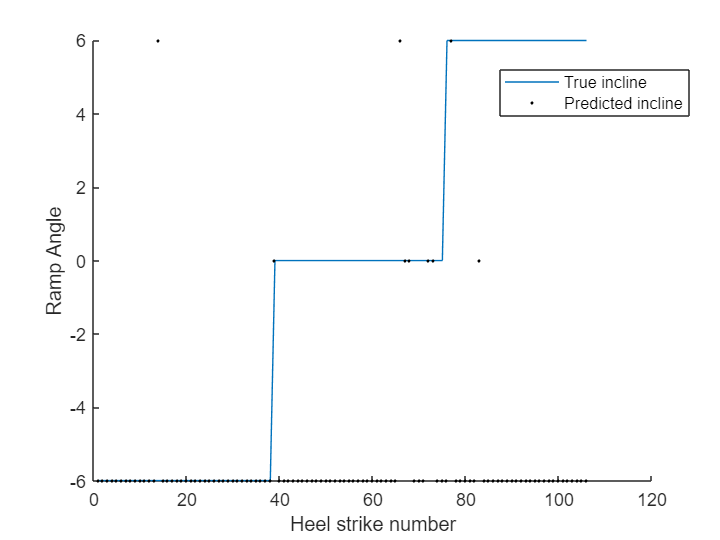


mdl = fitcdiscr(D_all.R_Accel, D_all.RampAngle);  % add the correct inputs to fitcdiscr()!
Predicted_Incline = predict(mdl, Samples);   % add the inputs to predict()!

figure; hold on
plot(Labels)
plot(Predicted_Incline,'k.',markersize=5)
xlabel('Heel strike number')
ylabel('Ramp Angle')
legend(["True incline", "Predicted incline"])

legend('Position',[0.69477,0.78616,0.2625,0.08625])

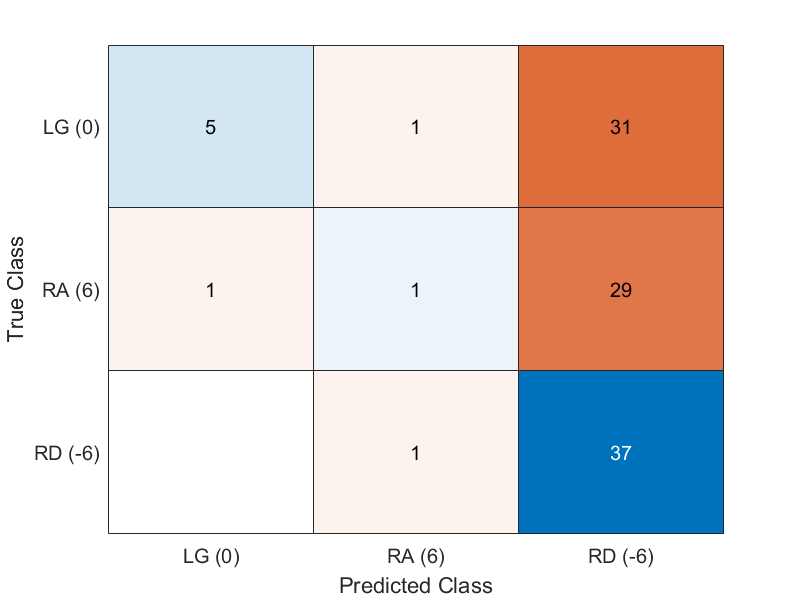

C = confusionmat(Labels,Predicted_Incline,'order',[-6 0 6]);
figure; confusionchart(C,{'RD (-6)', 'LG (0)', 'RA (6)'}); 

***Questions****:*

*Why might instantaneous values from the IMU have been a poor predictor of ramp angle?  [5]*

<your answer here>

IMU data can have the following error:

1) Noise. Need a lot of filter to get clear/good plots from the IMU data. Further, integration and differentitaion can amplify the noise.

2) Sensor placement: If during data collection, the sensor is moved or falls off, it can cause alot of error in the collected data.

3) Quality and Quantity of the data on which the model is trained.

*Other than time-history information from the IMU (which we'll discuss in 4.b), what other sensors do you suspect could have been helpful and why? [5]*

<your answer here>

As discussed in class, the following sensors would have been helpful: 

Load cell: can help us know the GRF which can be usedd for state change rules

Encoders: To measure the accurate angle at each joint

Pressure sensor: To know the center of pressure and determine the stance/swing phase based on that

Other sensors could be: EMG, Cameras and proximity sensors.

*According to the confusion matrix you generated above, what is the classification acccuracy and classification error for Ramp Ascent? [2]*

<your answer here>

Classification Accuracy: 1.4%

Classification Error: 98.6

*According to the confusion matrix you generated above, what is the classification acccuracy and classification error for Level Ground Walking? [2]*

<your answer here>

Classification Accuracy: 83%

Classification Error: 17%

## 4.b Feature Engineering

The instantaneous values did a fairly poor job of predicting ramp angle.  But we aren't making good use of data prior to the moment we make our prediction.  To do this in an efficent way, we will look at a window of data preceding heel strike (100 samples), and use features of this data: the max, mean, and min. 

**Modify GetFeatures.m**, which takes in the indices of interest (just_before_heel_strike_indices), window size, the data Table D_all, and a list of strings specifying the signalsToUse, and returns two variables: a matrix (#heel_strikes x 9) containing the mean, max and min for each of the three Acceleromater channels, and the Labels (ramp angle) for the corresponding heel strikes. [10]

*Note:* Try to use the variable "signalsToUse" if you can, which could be expanded to include other signals (e.g., it should work if signalsToUse = ["R_Accel", "R_Gyro"].  However you can get partial credit if you "hardcode" the use of "D_all.R_Accel" into the function.

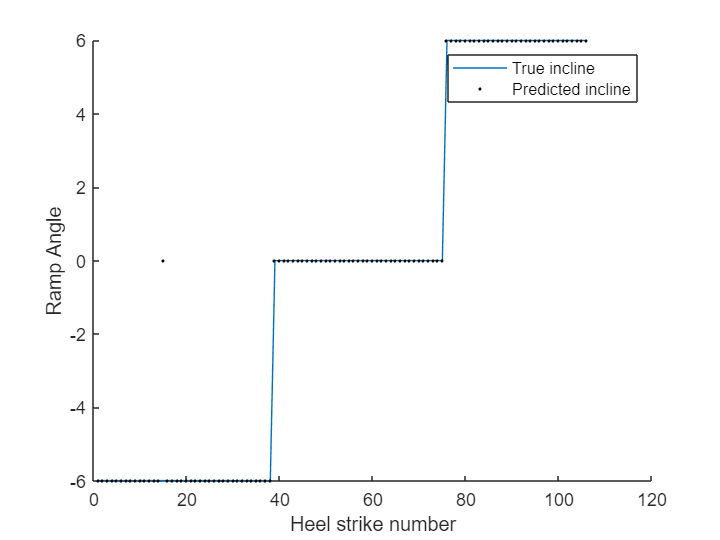

% Do not modify this code
signalsToUse = ["R_Accel"];
windowSize = 100;
[SamplesWithFeatures, Labels] = GetFeatures(just_before_HS_indices, windowSize, D_all, signalsToUse); % Modify GetFeatures.m

% Create a linear model
mdl = fitcdiscr(SamplesWithFeatures, Labels);
Predicted_Incline = predict(mdl, SamplesWithFeatures);

figure; hold on
plot(Labels)
plot(Predicted_Incline,'k.',markersize=5)
xlabel('Heel strike number')
ylabel('Ramp Angle')
legend(["True incline", "Predicted incline"])

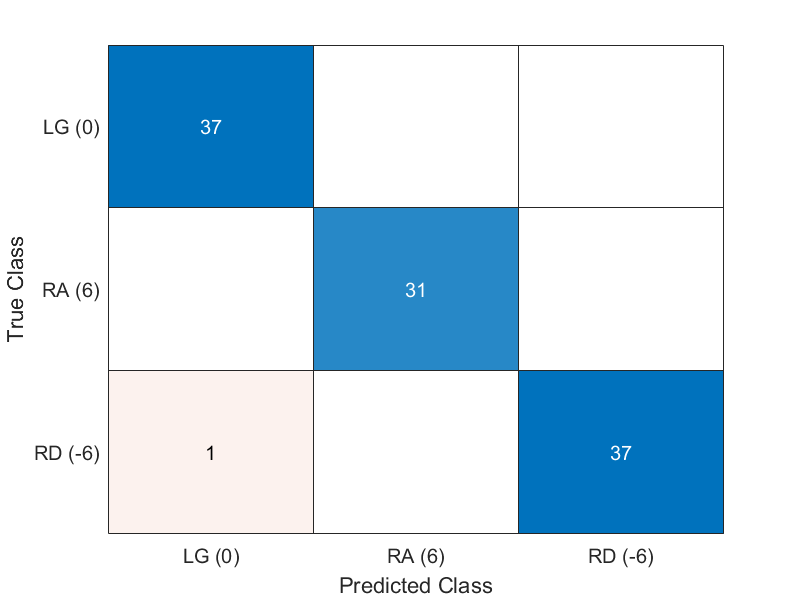

C = confusionmat(Labels,Predicted_Incline,'order',[-6 0 6]);
figure; confusionchart(C,{'RD (-6)', 'LG (0)', 'RA (6)'}); 

***Questions:***

*Why do you think this performed better? [5]*

<your answer here>

More quantity of data is provided by taking a window. This allows the model to understand the data better and hence better prdict the next movement, Hence the predicted and true class data is much better. Hence we can say that more training data allows us to have a better performance.

## To turn in the homework:

Don't forget the paper analysis! This is in a separate Word Doc, and is a separate "Assignment" on canvas. 

Make sure all plots are visible (re-run your code if you have to, but don't forget to zoom into the figures if you need to). Save this matlab file as a pdf.  **Upload this pdf to the Assignment: "HW 4 Part I: Prosthesis Mid-level Control."**

Next, upload your Paper analysis to "HW 4 Part II: Paper Analysis"

Finally, upload a zip folder containing your Matlab scripts (will help us debug if there were issues) to "HW 4 upload Matlab Files here"